%Experiment Number 1 - Curve Fitting
% Name of Programmer - Sahil Patra
% Roll No- 124MM0055
clc
clear all
n=input("Enter Number of Data Points ");
x = zeros(1, n);
y = zeros(1, n);
for i = 1:n
    x(i) = input('X= \n');
    y(i) = input('Y= \n');
end
sum_x = 0;
sum_y = 0;
sum_2_x = 0;
sum_x_y = 0;

for i = 1:n
    sum_x = sum_x + x(i);
    sum_y = sum_y + y(i);
    sum_2_x = sum_2_x + x(i)^2;
    sum_x_y = sum_x_y + x(i) * y(i);
end
A=[sum_2_x sum_x;
    sum_x n];
B=[sum_x_y; 
    sum_y];
X=A\B;
m = X(1);
c = X(2);
fprintf('Best Fit Straight Line y = %fx+%f ', m,c)

Best Fit Straight Line y = 11.600000x+4.000000 

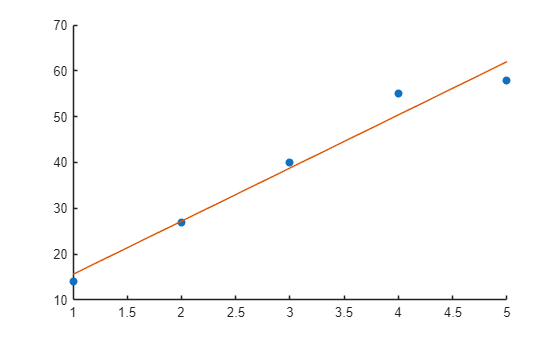

figure(1)
scatter(x,y,"filled")
hold on
y_fitted=m*x+c;
plot(x,y_fitted)

% Goodness of fit 
y_mean= sum_y/n;
SS_res = sum((y - y_fitted).^2); 
SS_tot = sum((y - y_mean).^2);   
G= (SS_tot-SS_res)/SS_tot;
fprintf('Goodness of Fit : %f\n', G);

Goodness of Fit (R^2): 0.970291
